# **2.3.2 零阶保持器**

### **试画出零阶保持器的幅值谱和相位谱，和已知的学习结果比较，并进行分析 （采样频率 10Hz，请计算出 0 频率处的幅值谱）。**

#### 零阶保持器的作用是在信号传递过程中，把第nT时刻的[采样信号](https://baike.so.com/doc/7963875.html)值一直保持到第(n+1)T时刻的前一瞬时，把第(n+1)T时刻的采样值一直保持到(n+2)T时刻，依次类推，从而把一个脉冲序列变成一个连续的阶梯信号。因为在每一个采样区间内连续的阶梯信号的值均为常值，亦即其一阶导数为零，故称为零阶保持器

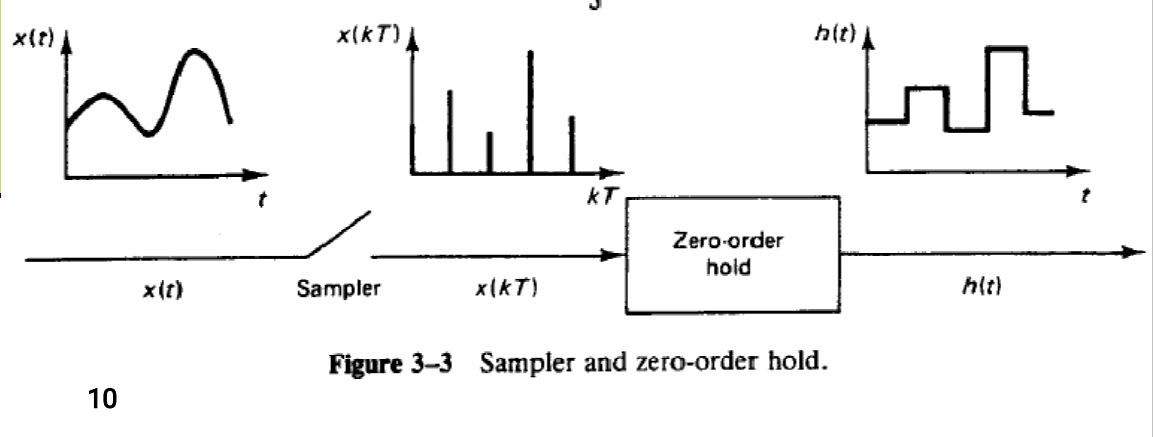

### 零阶保持器的传递函数：


$$\mathrm{Gh}\left(s\right)=\frac{\left(1-e^{-\mathrm{Ts}} \right)}{s}$$



$$\mathrm{Gh}\left(w\right)=\frac{\left(1-e^{-\mathrm{Tjw}} \right)}{\mathrm{jw}}$$


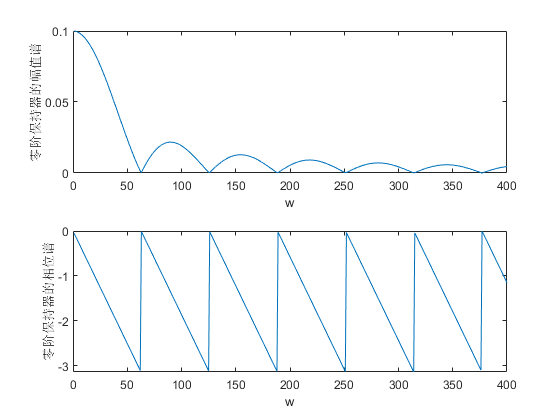

fs = 10;
w = 0:400;
T = 1/fs;
g = (1-exp(-T*1i*w))./(1i*w);
% 幅值谱
subplot(2,1,1);
plot(w,abs(g));
ylabel('零阶保持器的幅值谱');
xlabel('w');
% 相位谱
subplot(2,1,2);
plot(w,angle(g));
ylabel('零阶保持器的相位谱');
xlabel('w');

# 结论：

### 零阶保持器的幅值随频率w的增大而衰减；零阶保持器存在相位滞后。

### 零阶保持器百具有低通滤波特性，还可以允许部分高频分量通过；零阶保持器结构比较简单。

### 零阶保持器的引入的话，可能会导致系统稳定性下降。